# Categorical Data with RBF Kernel

Performs outlier detection on the a categorical data set with a radial kernel. The categories are assigned randomly from a uniform distribution.

## Setup

clc;
clear all;
close all;
rng(1634256, "twister");

addpath(genpath(fileparts(which(mfilename))));

## Colors & Fonts

Create some colors for the figures

color_BLUE      = "#00B3EF";
color_ORANGE    = "#EF7600";
color_GREEN     = "#00B31A";
color_GREY      = "#404040";
color_RED       = "#cd0000";

markers = {".", "+", "o", "square"};

fontSize = 10;
mSize = 8;

## Sample Dataset

epsilon =0.2

epsilon = 0.2000

alpha = 0.75

alpha = 0.7500

N = 1000; N1 = ceil((1-epsilon)*N); N2 = N - N1;        
data = halfkernel(N1,N2, -20, 20, 40, 5, 0.6);
mask = logical(data(:,3));
x = data(:, 1:2);
y = data(:, 3);   
ind = randperm(size(x, 1), size(x, 1));
x=x(ind, :);
y=y(ind, :);

% add random category to data
d =  datasample(1:4, N)';
x = [x, datasample(1:4, N)'];
x = rZscores(x); 

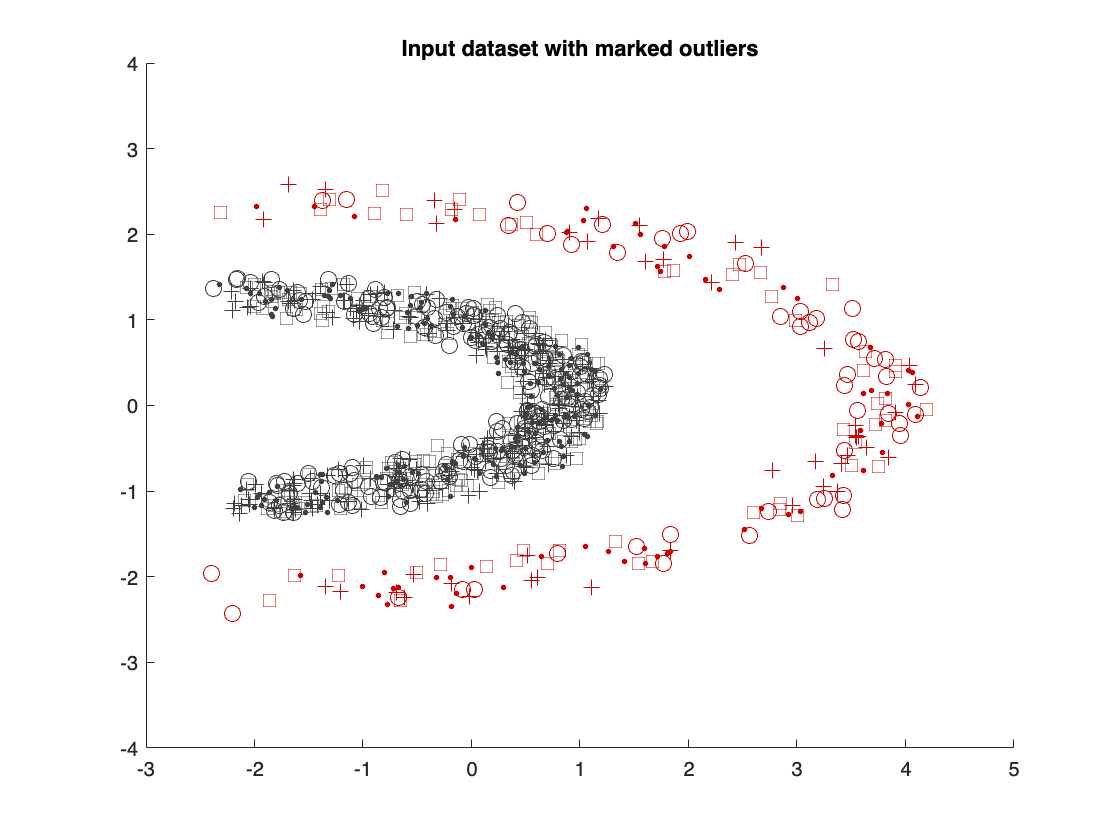

[rr, cc] = meshgrid(-5:0.1:5, -5:0.1:5);
yy=[rr(:), cc(:)];    
fig = figure(1);

hold on;

for i = 1:4
    plot(x(y>0 & d==i, 1), x(y>0 & d==i, 2), markers{i}, 'color', color_GREY, 'MarkerSize', mSize); 
    plot(x(y==0 & d==i, 1), x(y==0 & d==i, 2), markers{i}, 'color', color_RED, 'MarkerSize', mSize);
end

hold off;

set(gca,'FontSize',fontSize);
colormap bone;
set(gcf,'color','w');
ylim([-4, 4]);
title('Input dataset with marked outliers');

## Computation

kModel = AutoRbfKernel(x);

AutoRbfKernel: Sigma = 2.7976079345561


poc = kMRCD(kModel);
solution = poc.runAlgorithm(x, alpha);

Convergence at iteration 4, SDO
Convergence at iteration 4, SpatialRank
Convergence at iteration 5, SpatialMedian
Convergence at iteration 5, SSCM
-> Best estimator is SSCM


rho = solution.rho;
scfac = solution.scfac;

## Result

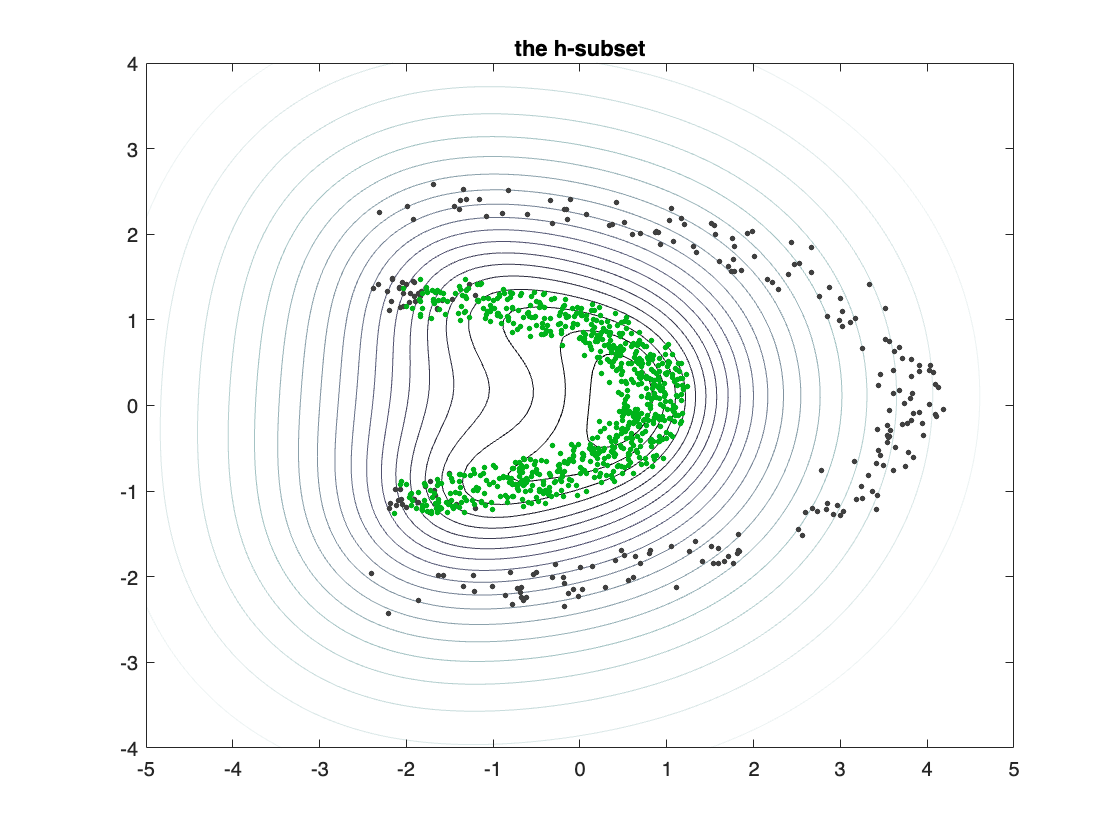

[rr, cc] = meshgrid(-5:0.1:5, -5:0.1:5);        
yy=[rr(:), cc(:)];
yy(:,3) = 0;

Kx = kModel.compute(x(solution.hsubsetIndices, :), x(solution.hsubsetIndices, :));
nx = size(Kx,1);
Kt = kModel.compute(yy, x(solution.hsubsetIndices, :));
Kc = Utils.center(Kx);
Kt_c = Utils.center(Kx,Kt);
Ktt_diag = diag(kModel.compute(yy,yy)); % Precompute
Kxx = Ktt_diag - (2/nx)*sum(Kt,2) + (1/nx^2)*sum(sum(Kx));
smdMesh = (1/rho)*(Kxx - (1-rho)*scfac*sum((Kt_c/((1-rho)*scfac*Kc + nx*rho*eye(nx)).*Kt_c),2)); 

ss = logical(y);

figure(2);         
contour(rr, cc, reshape(log(smdMesh), size(rr)), 20); hold on;        
plot(x(:, 1), x(:, 2), '.', 'color', color_GREY, 'MarkerSize', mSize);
plot(x(solution.hsubsetIndices, 1), x(solution.hsubsetIndices, 2), '.', 'color', color_GREEN, 'MarkerSize', mSize);
set(gca,'FontSize',fontSize);
hold off;
colormap bone;
set(gcf,'color','w');
ylim([-4, 4]);
title('the h-subset');

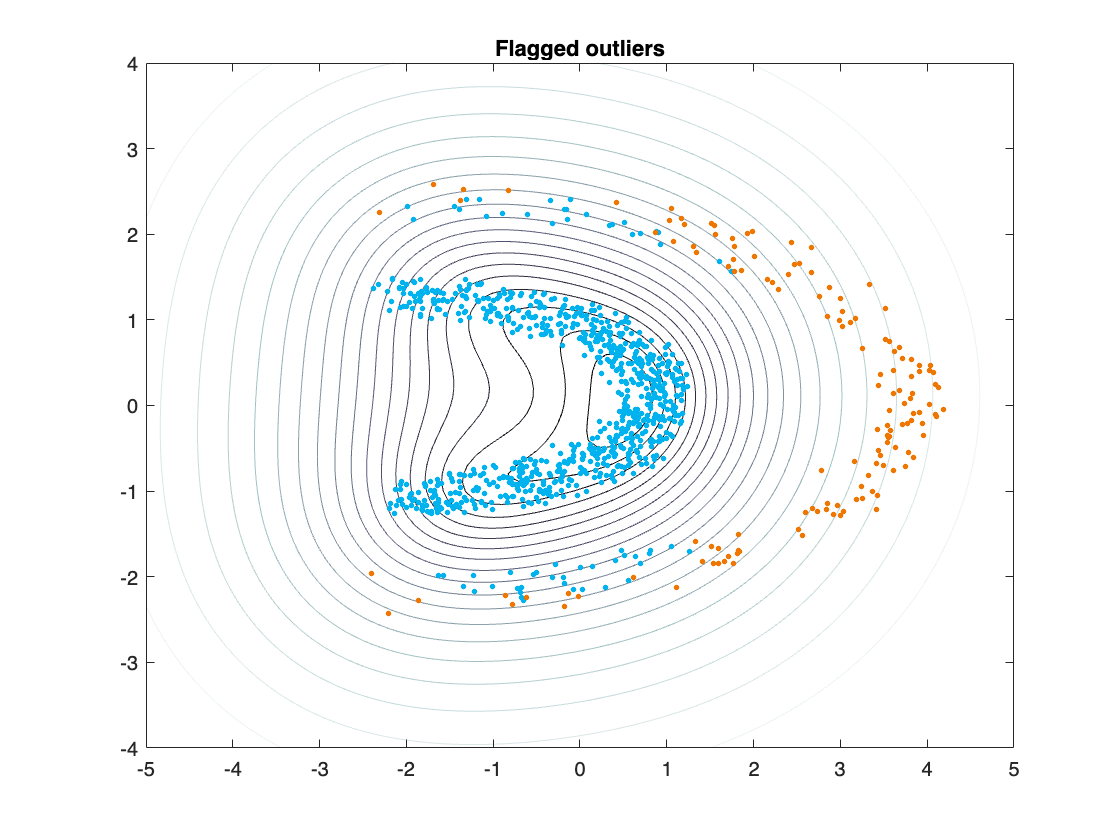


figure(3);        
contour(rr, cc, reshape(log(smdMesh), size(rr)), 20); hold on;
plot(x(:, 1), x(:, 2), '.', 'color', color_BLUE, 'MarkerSize', mSize);
plot(x(solution.flaggedOutlierIndices, 1), x(solution.flaggedOutlierIndices, 2), '.', 'color', color_ORANGE, 'MarkerSize', mSize);
hold off;
colormap bone;
set(gcf,'color','w');
ylim([-4, 4]);
set(gca,'FontSize',fontSize);
title('Flagged outliers');

## Evaluation

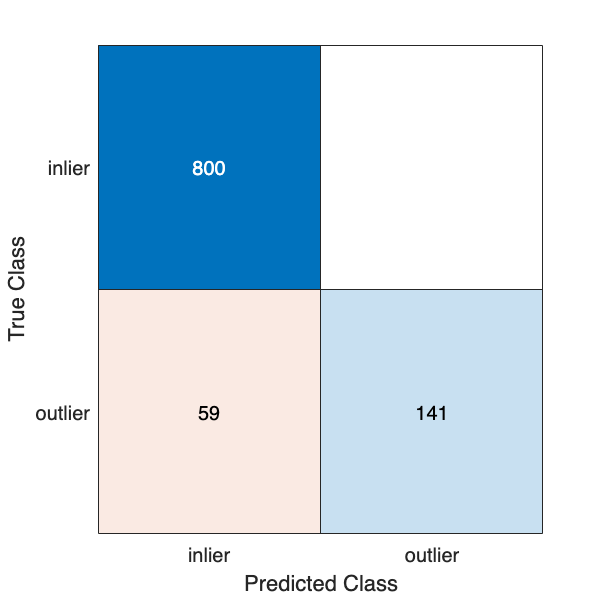

group = categorical(y, [1, 0], ["inlier", "outlier"]);

grouphat = categorical(repmat("inlier", size(y)), ["inlier", "outlier"]);
grouphat(solution.flaggedOutlierIndices) = "outlier";

figure(4);
cm = confusionchart(group,grouphat);
set(gcf,'Position',[100, 100, 300, 300]);


true_negatives = cm.NormalizedValues(1,1);
false_negatives = cm.NormalizedValues(2,1);

true_positives = cm.NormalizedValues(2,2);
false_positves = cm.NormalizedValues(1,2);

accuracy = (true_positives + true_negatives)/size(data, 1);
precision = true_positives / (true_positives + false_positves);
sensitivity = true_positives / (true_positives + false_negatives);
specificity = true_negatives / (true_negatives + false_positves);

table(accuracy, precision, sensitivity, specificity)

ans = 1×4 table
    accuracy    precision    sensitivity    specificity
    ________    _________    ___________    ___________

     0.941          1           0.705            1     
